## Introduction

In this scrip, we just try to test the calcualtion of residual（残差）. This version  uses 3 parameters: m, zeta and psi. The ranges of parameters come from fv3.1_3p_grid_search.

With the efficient of grid searching, its hard to get to precis parameter. We use **Gradient descent **to get the precise parameter values.

## Import data and previewing

figure
data_name='p47_5s'

data_name = 'p47_5s'

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
plot(eval(['MSD_',data_name,'_All']).MSD_PP(:,1),'LineWidth',2)
legend('x','y','z','Location',"best");

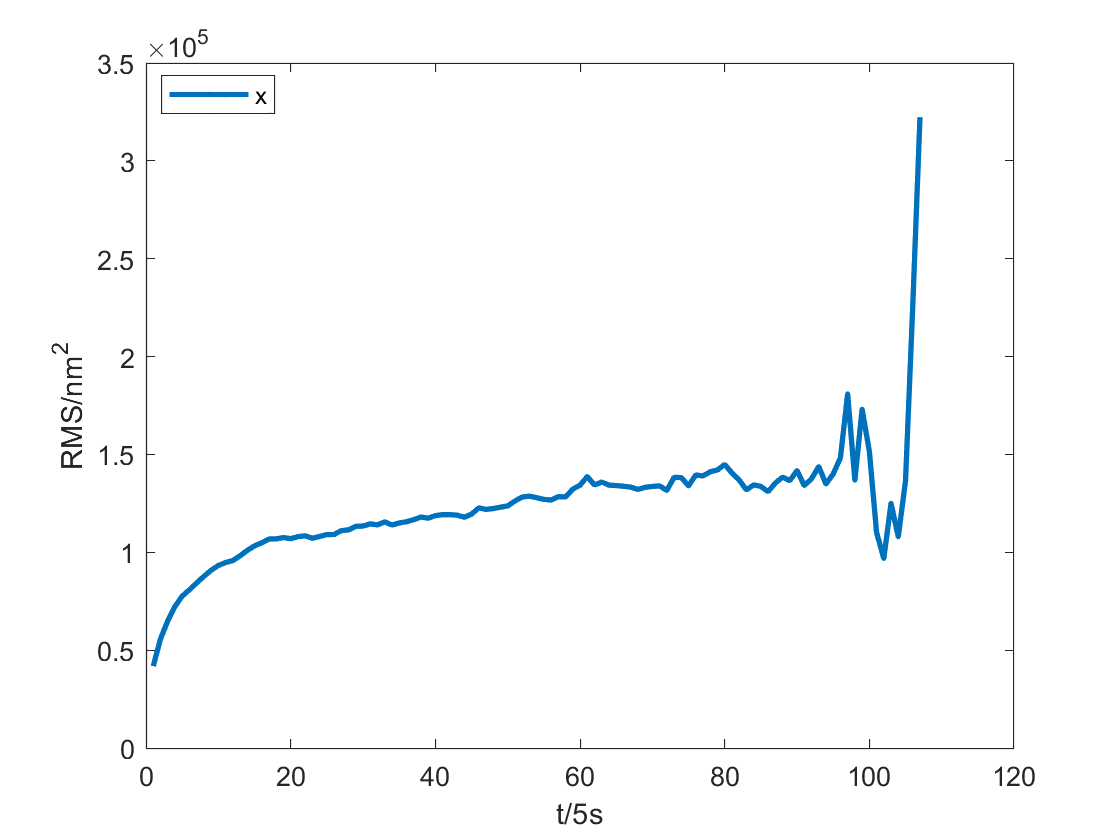

xlabel('t/5s')
ylabel('RMS/nm^2')

cut down the declining part, we delete all data after the maximum one.

Reserved_lengths=zeros(3,1);
experiment_interval=5

experiment_interval = 5

X part

%experiment_MSDX=eval(['MSD_',data_name,'_All']).MSD_PP(:,1);
%max_experiment_MSDX=max(experiment_MSDX);
Reserved_lengths(1,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)));
interceptive_experiment_MSDX=1e-18*eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths(1,1),1);

Y part

%Reserved_lengths(2,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)));
%interceptive_experiment_MSDY=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths(2,1),2);

Z part

%Reserved_lengths(3,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)))
%interceptive_experiment_MSDZ=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths,3);

## Data Importing

import Time interval

delta=0.1;

import Total_experiment_number

Total_experiment_number=1000;

data import

Reserved_length=Reserved_lengths(1,1);
interceptive_experiment_MSD=interceptive_experiment_MSDX;

## Initilizing parameters

input the initial parameter

m_0=2e-9;
psi_0=5e-8;
zeta_0=2e-8;

put it in use

m=m_0

m = 2.0000e-09

psi=psi_0

psi = 5.0000e-08

zeta=zeta_0

zeta = 2.0000e-08

H=0.75

H = 0.7500

decide step length and sample length (proportional)

step_length=1/10;
sample_length=1/100;

add parameter history and gradient history

parmeter_history=[m,zeta,psi];
gradient_history=[];

## Calculating decline in three direction

for step_number=1:10
    residual_0=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m,delta,Total_experiment_number);
    residual_m=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m*(1+sample_length),delta,Total_experiment_number);
    residual_psi=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi*(1+sample_length),zeta,H,m,delta,Total_experiment_number);
    residual_zeta=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta*(1+sample_length),H,m,delta,Total_experiment_number);
    gradient=[residual_m-residual_0,residual_psi-residual_0,residual_zeta-residual_0]/sample_length;
    unit_gradient=gradient/norm(gradient);

make new parameter in the opposute direction of gradient

    m=m*(1-unit_gradient(1)/20)
    psi=psi*(1-unit_gradient(2)/20)
    zeta=zeta*(1-unit_gradient(3)/20)
    parmeter_history=[parmeter_history;[m,zeta,psi]];
    gradient_history=[gradient_history;gradient];
end

## saving

saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.G.D'
save([saving_location,'\data\history data N=',num2str(Total_experiment_number),'step=',num2str(step_length),datestr(now,'yyyy-mm-dd HH')],'parmeter_history','gradient_history')

## Plot and plot saving: paramter history

figure
plot3(parmeter_history(:,1),parmeter_history(:,2),parmeter_history(:,3),'k-o','MarkerFaceColor','k');
hold on
for i=1:step_number
    quiver3(parmeter_history(i,1),parmeter_history(i,2),parmeter_history(i,3),parmeter_history(i,1)*(gradient_history(i,1)),parmeter_history(i,2)*(gradient_history(i,2)),parmeter_history(i,3)*(gradient_history(i,3)),1e19);
end
hold off
xlabel('m/kg')
ylabel('\psi/A.U.')
zlabel('\zeta/A.U.')
title({'parameter changing',['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)

saving

saveas(gcf,[saving_location,'\image\parameter history image N=',num2str(Total_experiment_number),' step=',num2str(step_length),' ',datestr(now,'yyyy-mm-dd HH'),'.png'])

## Plot and plot saving: gradient history

figure
plot(residual_history,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^2')
title({'residual changing',['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)

saving

saveas(gcf,[saving_location,'\image\residual history image N=',num2str(Total_experiment_number),' step=',num2str(step_length),' ',datestr(now,'yyyy-mm-dd HH'),'.png'])